clc;
clear all;
close all;

%   DH  = [  a_n  alpha_n  d_n  theta_n]
DHparameter=[0 0 0.04 0;
             0.12 pi/2 0 13*pi/30;
             0.194 0 0 -23*pi/30;
             0 -pi/2 0.176 0;
             0 pi/2 0 pi/2;
             0 pi/2 0 0];

%Defining a Robot Rigid Body Tree 
dental = robotics.RigidBodyTree;

%Setting the Gravity matrix w.r.t to the base frame of robot.
dental.Gravity = [0 0 -9.81];

%Creating links and joints
body1 = robotics.RigidBody('Body1');
joint1 = robotics.Joint('Joint1','revolute');
body1.Mass = 10;
body1.CenterOfMass = [0 0 0];
joint1.PositionLimits = [0 2*pi];
body2 = robotics.RigidBody('Body2');
joint2 = robotics.Joint('Joint2','revolute');
body2.Mass = 10;
body2.CenterOfMass = [0 0 0];
joint2.PositionLimits = [-2*pi/3 0];

body3 = robotics.RigidBody('Body3');
joint3 = robotics.Joint('Joint3','revolute');
body3.Mass = 10;
body3.CenterOfMass = [0 0 0];
joint3.PositionLimits = [-pi/3 pi/3];

body4 = robotics.RigidBody('Body4');
joint4 = robotics.Joint('Joint4','revolute');
body4.Mass = 10;
joint4.PositionLimits = [0 2*pi];

body5 = robotics.RigidBody('Body5');
joint5 = robotics.Joint('Joint5','revolute');
body5.Mass = 10;
joint5.PositionLimits = [-pi/4 pi/4];

body6 = robotics.RigidBody('Body6');
joint6 = robotics.Joint('Joint6','revolute');
body6.Mass = 10;
joint6.PositionLimits = [-pi/4 pi/4];

body7 = robotics.RigidBody('Body7');
joint7 = robotics.Joint('Joint7','prismatic');
body7.Mass = 10;
% joint7.PositionLimits = [0.2 10];

%Settings the transformations to each joint with DH parameter.
%Assigning the joint of each link with the object 
setFixedTransform(joint1,DHparameter(1,:),"dh");
body1.Joint = joint1;
setFixedTransform(joint2,DHparameter(2,:),"dh");
body2.Joint = joint2;
setFixedTransform(joint3,DHparameter(3,:),"dh");
body3.Joint = joint3;
setFixedTransform(joint4,DHparameter(4,:),"dh");
body4.Joint = joint4;
setFixedTransform(joint5,DHparameter(5,:),"dh");
body5.Joint = joint5;
setFixedTransform(joint6,DHparameter(6,:),"dh");
body6.Joint = joint6;
setFixedTransform(joint7,DHparameter(6,:),"dh");
body7.Joint = joint7;

addBody(dental,body1,'base');
addBody(dental,body2,'Body1');
addBody(dental,body3,'Body2');
addBody(dental,body4,'Body3');
addBody(dental,body5,'Body4');
addBody(dental,body6,'Body5');
addBody(dental,body7,'Body6');

dental.DataFormat = 'column'

dental =   rigidBodyTree with properties:

     NumBodies: 7
        Bodies: {[1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]}
          Base: [1×1 rigidBody]
     BodyNames: {'Body1'  'Body2'  'Body3'  'Body4'  'Body5'  'Body6'  'Body7'}
      BaseName: 'base'
       Gravity: [0 0 -9.8100]
    DataFormat: 'column'



showdetails(dental)

--------------------
Robot: (7 bodies)

 Idx    Body Name    Joint Name    Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------    ----------    ----------    ----------------   ----------------
   1        Body1        Joint1      revolute             base(0)   Body2(2)  
   2        Body2        Joint2      revolute            Body1(1)   Body3(3)  
   3        Body3        Joint3      revolute            Body2(2)   Body4(4)  
   4        Body4        Joint4      revolute            Body3(3)   Body5(5)  
   5        Body5        Joint5      revolute            Body4(4)   Body6(6)  
   6        Body6        Joint6      revolute            Body5(5)   Body7(7)  
   7        Body7        Joint7     prismatic            Body6(6)   
--------------------



% show(dental);

% Read and plot complete denture
stlData = stlread('stl/1-3dm.stl');
points = stlData.Points;
ptCloud = pointCloud(points);
% figure
% pcshow(ptCloud)


% Select and plot three teeth individually
roi = [-60 -40 10 40 -6 6]; % region of interest
indices = findPointsInROI(ptCloud,roi);
ptCloudB = select(ptCloud, indices);
% pcshow(ptCloudB.Location);

% Import and plot final model individually
stlData_fin = stlread("stl/1tooth_mesh2.STL");

points_fin= stlData_fin.Points;
ptCloud_fin = pointCloud(points_fin);
% pcshow(ptCloud_fin);


% Three teeth in the denture
% figure
% pcshow(ptCloud);
% hold on;
% pcshow(ptCloudB.Location,'r');
% legend('Point Cloud','Points within ROI','Location','southoutside','Color',[1 1 1])
% xlabel('X'); ylabel('Y'); zlabel('Z');
% hold off;


% Final tooth inside the considered tooth
% figure
% pcshow(ptCloudB.Location);
% hold on;
% pcshow(ptCloud_fin);
% hold off;

%Transformation (shrink and move)
Sx = 0.011;
Sy = 0.011;
Sz = 0.011;


tform = affine3d([Sx 0 0 0; 0 Sy 0 0; 0 0 Sz 0; 0 0 0 1]);
ptCloud_3t = pctransform(ptCloudB,tform);
ptCloud_fin = pctransform(ptCloud_fin,tform);
rot = [1 0 0; 0 1 0; 0 0 1];
zCoord = -0.1;
trans = [0.9 -0.35 zCoord];
tform = rigid3d(rot,trans);
ptCloud_3t = pctransform(ptCloud_3t,tform);
ptCloud_fin = pctransform(ptCloud_fin,tform);

% figure
% pcshow(ptCloud_3t)
% xlabel('X'); ylabel('Y'); zlabel('Z')

% pcshow(ptCloud_fin)
% xlabel('X'); ylabel('Y'); zlabel('Z')

MSH = collisionMesh(ptCloud_fin.Location);
worldCollisionArray = {MSH};
% figure;
% show(dental)
% hold on;
% pcshow(ptCloud_fin)
% ax = exampleHelperVisualizeCollisionEnvironment(worldCollisionArray);

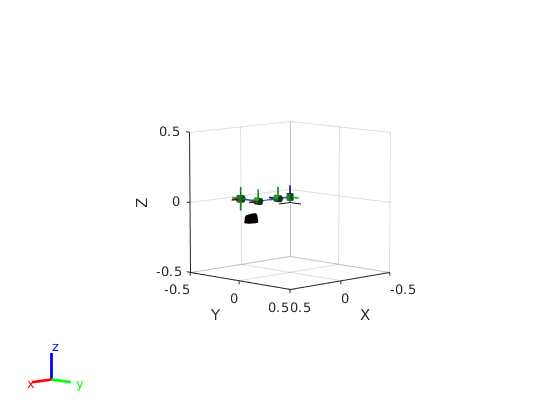

collisionObj = collisionCylinder(0.025,0.05);

for i = 1:dental.NumBodies
    addCollision(dental.Bodies{i},collisionObj)
end

figure
show(dental,homeConfiguration(dental),"Collisions","on"); hold on;
show(MSH)
l = 0.5;
axis([-l l -l l -l l])
hold on;

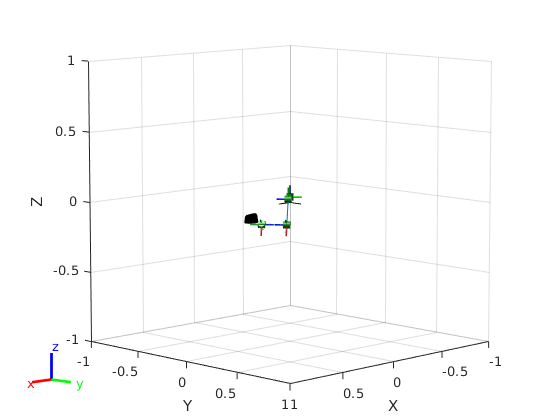

point = [0.3 0 -0.25];

ik = inverseKinematics('RigidBodyTree',dental);
weights = [0 0 0 1 1 1];
qInitial = dental.homeConfiguration;
endEffector = 'Body6';
qSol = ik(endEffector,trvec2tform(point),weights,qInitial);

figure
show(dental,qSol,"Collisions","on"); hold on;
show(MSH)


isColliding = checkCollision(dental,qSol,worldCollisionArray)

isColliding = 1×2 logical array
   1   0


function [ax, figHandle] = exampleHelperVisualizeCollisionEnvironment(collisionObjectArray)
%exampleHelperVisualizeCollisionEnvironment Visualize a set of collision objects
%   given a cell array of collision objects, create a figure that plots
%   these and with hold on. Return the handle to the figure's axis.
figHandle = figure;

% Show the first object
show(collisionObjectArray{1});

% Get axis properties and set hold
ax = gca;
hold all;

% Show remaining objects
for i = 2:numel(collisionObjectArray)
    show(collisionObjectArray{i}, "Parent", ax);
end

% Set axis properties
axis equal;

end
